% Read data from file
fid = fopen('.\Data\ev_dif\f4.txt', 'r'); %这样读入
if fid == -1
    error('File data.txt not found. Please ensure the file exists.');
end
data = fread(fid, '*char')';
fclose(fid);

% Extract all RX Timestamps
rx_pattern = 'RX Timestamp: (\d+)';
rx_matches = regexp(data, rx_pattern, 'tokens');
if isempty(rx_matches)
    error('No RX Timestamps found in the data.');
end
%这里的rx_matches是返回所有匹配rx_pattern的数组、
rx_timestamps = zeros(length(rx_matches), 1);
for i = 1:length(rx_matches)
    rx_timestamps(i) = str2double(rx_matches{i}{1});
end
rx_timestamps

rx_timestamps = 1.0e+12 *

    0.4865
    0.4897
    0.6306
    0.6338
    0.7748
    0.7780
    0.9189
    0.9221
    1.0631
    1.0663


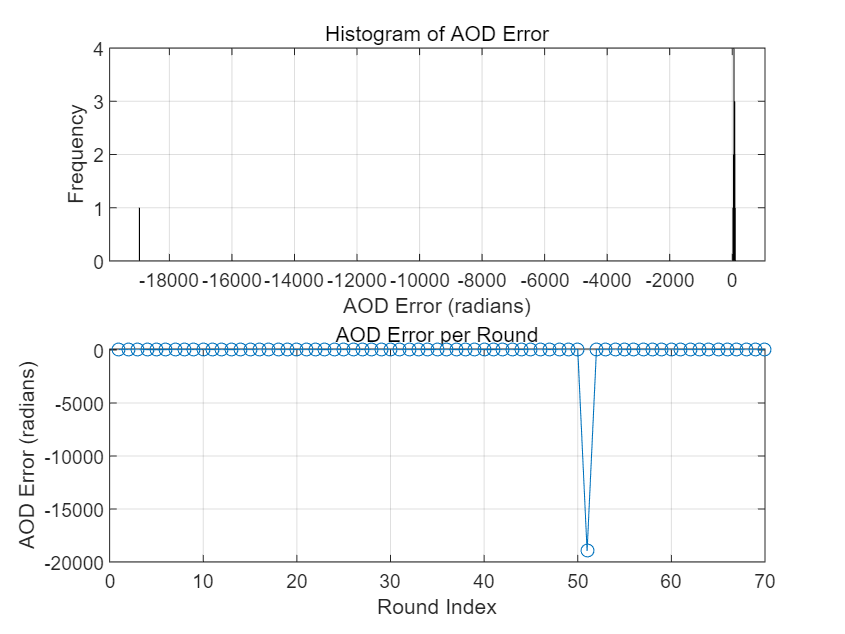

% Extract all Clock Offset Hz values
co_pattern = 'Clock Offset: ([\d\.]+) Hz';
co_matches = regexp(data, co_pattern, 'tokens');
if isempty(co_matches)
    error('No Clock Offset values found in the data.');
end
clock_offsets = zeros(length(co_matches), 1);
for i = 1:length(co_matches)
    clock_offsets(i) = str2double(co_matches{i}{1});
end

% Check if number of RX Timestamps and Clock Offsets are equal
if length(rx_timestamps) ~= length(clock_offsets)
    error('Number of RX Timestamps and Clock Offsets do not match.');
end

% For every two consecutive packets, form a round
num_rounds = floor(length(rx_timestamps) / 2);
if num_rounds == 0
    error('Insufficient data for rounds.至少需要两个数据包。');
end
aod_errors = zeros(1, num_rounds);
test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的

mean_CFO = mean(clock_offsets); %将计算出来的CFO取一个平均值
for i = 1:num_rounds
    idx1 = 2*i - 1;
    idx2 = 2*i;
    T1 = rx_timestamps(idx1);
    T2 = rx_timestamps(idx2);
    CFO = clock_offsets(idx1); % 使用每轮第一个数据包的Clock Offset
    
    delta_t = (T2 - T1) / 1e12 ; % 转换为秒
    test_time(i) = delta_t;
    aod_errors(i) = 2 * pi * delta_t * mean_CFO; % 计算AOD_error
    %这里直接使用平均值mean计算
end

% Plot histogram and line plot
figure;
subplot(2,1,1);
histogram(aod_errors, 'BinWidth', 0.5); % 调整BinWidth以适应数据
title('Histogram of AOD Error');
xlabel('AOD Error (radians)');
ylabel('Frequency');
grid on;

subplot(2,1,2);
plot(1:num_rounds, aod_errors, '-o');
title('AOD Error per Round');
xlabel('Round Index');
ylabel('AOD Error (radians)');
grid on;


% Compute mean and standard deviation
mean_aod = mean(aod_errors);
std_aod = std(aod_errors);

fprintf('Mean AOD error: %.6f radians\n', mean_aod);

Mean AOD error: -206.670511 radians


fprintf('Standard deviation of AOD error: %.6f radians\n', std_aod);

Standard deviation of AOD error: 2273.823135 radians



fprintf('Mean AOD error(ppm): %.6f deg\n',0.000154*mean_aod*180/pi);

Mean AOD error(ppm): -1.823568 deg



mean_time = mean(test_time);
std_time = std(test_time);
fprintf('Mean AOD error: %.6f radians\n', mean_time);

Mean AOD error: -0.012504 radians


fprintf('Standard deviation of AOD error: %.6f radians\n', std_time);

Standard deviation of AOD error: 0.131417 radians


%好消息，时间戳之差非常稳定